# Example 1: executing a simulation

### This assumes the database and default data has been loaded 

## 1. Connect to the database and select a UAV

% get the root directory
file_path = strsplit(fileparts(matlab.desktop.editor.getActiveFilename), '\');
idx = find(strcmp(file_path, 'uavTestbed'));
root_directory = strjoin(file_path(1:idx), '\')

root_directory = 'G:\Dropbox\NASA\uavTestbed2\test\uavTestbed'

% switch to the root directory
cd(root_directory);

% load the workspace paths
addpath(genpath(root_directory));
clear('file_path', 'idx', 'root_directory');

% the database connection
conn = db_connect('nasadb');

% check out what UAVs are in the db
uav_tb = select(conn, 'select asset_tb.serial_number, uav_tb.* from uav_tb join asset_tb on asset_tb.id = uav_tb.id;')

uav_tb = 1×13 table
    serial_number    id    airframe_id    battery_id    m1_id    m2_id    m3_id    m4_id    m5_id    m6_id    m7_id    m8_id    max_flight_time
    _____________    __    ___________    __________    _____    _____    _____    _____    _____    _____    _____    _____    _______________

     {'E818D0'}      11         1             2          10        9        8        7        6        5        4        3            18       


% load the UAV 
uav = load_uav(conn, uav_tb.serial_number{1})

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
             motors: [8×1 struct]
    max_flight_time: 18
                 id: 11
     dynamics_srate: 0.0250
               mass: 1.8000


### Load the stop_code_tb and group_tb

### Look at the flight summary table and get the last timestamp and flight_id

- since these are simulations, the simulation time will grow beyond real time so we cannot just use " datestr(now) " as the start time

- The start time is important because the telemetry data is indexed via timestamp

- the start and stop timestamps in the flight_summary_tb are used to access the flight telemetry data for that flight

- the flight_id refers to the id field of flight_summary_tb

% to match stop codes with the simulation
% new stop codes for your specific experiment can be created
stop_code_tb = select(conn, "select * from stop_code_tb;")

stop_code_tb = 6×2 table
    id           description        
    __    __________________________

    1     {'low soc'               }
    2     {'low voltage'           }
    3     {'max position error'    }
    4     {'arrival success'       }
    5     {'average position error'}
    6     {'low soh (battery)'     }


% for organizing multiple executions
group_id_tb = select(conn, "select * from group_tb")

group_id_tb = 1×2 table
    id        info    
    __    ____________

    1     {'examaple'}


group_id = group_id_tb.id(1);

% get the start time
dt_last = table2array(select(conn, 'select mt.dt_stop from flight_summary_tb mt order by dt_stop desc limit 1;'));
if ~isempty(dt_last)
    dt_last = datetime(dt_last);
end

if isempty(dt_last)
    % the first entry into flight_summary_tb is now
    dt_start = datetime(now, 'ConvertFrom', 'datenum');
else
    % this entry into flight_summary_tb is the last entry + 1 minute
    dt_start = dt_last + minutes(1);
end
dt_start = datetime(dt_start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
dt_start = dateshift(dt_start, 'start', 'second')

dt_start = datetime
   30-Jul-2021 10:53:39


% get the flight_id
flight_id = table2array(select(conn, 'select id from flight_summary_tb order by id desc limit 1;')) + 1


flight_id =

  0×1 empty double column vector



if isempty(flight_id)
    flight_id = 1;
end
% close the connection and clear the table (the data is in the uav struct now)
conn.close();
clear('uav_tb', 'conn');

## 2. Setup the simulation parameters

% stop measure on the simulation, in general it should stop before this
sim_params.max_sim_time = 2400;

% performance thresholds
sim_params.perf_param_thresh.max_pos_err  = 6.5; % this is check in the simulation
sim_params.perf_param_thresh.min_soc      = .3; % this is check in the simulation
sim_params.perf_param_thresh.min_v        = uav.battery.EOD * 1.2; % this is checked in the simulation
sim_params.perf_param_thresh.min_soh_batt = uav.battery.Q * .6; % this is checked after
sim_params.perf_param_thresh.avg_pos_err  = 2.8; % this is checked after

% controller and filter estimation parameters, initial conditions for the UAV
sim_params.controllers         = load('params/controllers.mat').controllers;
sim_params.initial_conditions  = load('params/IC_HoverAt10ftOcto.mat').IC;
sim_params.battery_estimator   = load('estimation/batteryestimator').BatteryEstimator;
sim_params.position_estimator  = load('estimation/positionestimator').PositionEstimator;
sim_params.motor_estimator     = load('estimation/MotorEstimator').MotorEstimator;

% wind (really need a better implementation of wind)
processes.environment.wind.gust = [1.2, .5];

## 3. Load the trajectory

% load the trajectory information
% there are 37 different trajectories, this function will return one that
% is closest to the second parameter in the function (uav.max_flight_time)
% with valid numbers (minutes) between 6 and 22. 
%trajectory = get_trajectory('trajectories/trajectories.csv', uav.max_flight_time);
trajectory = get_trajectory('trajectories/trajectories.csv', 8);

% update initial conditions
sim_params.initial_conditions.X = trajectory.x_ref_points(1,2);
sim_params.initial_conditions.Y = trajectory.y_ref_points(1,2);
sim_params.initial_conditions.state(1) = trajectory.x_ref_points(1,2);
sim_params.initial_conditions.state(2) = trajectory.y_ref_points(1,2);

% set the desired velocity
trajectory.velocity = 1.3; % m/s

## 4a. Simulate

- give it a "flight_num" also, unless the flights need to relate to each other you can always keep this as 1

flight_num = 1;
tic
sim('simulink/uav_simulation.slx');
toc

Elapsed time is 131.999832 seconds.


#### calculate dt_stop

dt_stop = dt_start + minutes(time.Data(end, 1))

dt_stop = datetime
   30-Jul-2021 11:01:26


## 4b. check stop codes and system performance parameter thresholds

- stop codes 1-4 are checked in simulation

stop_code_tb

stop_code_tb = 6×2 table
    id           description        
    __    __________________________

    1     {'low soc'               }
    2     {'low voltage'           }
    3     {'max position error'    }
    4     {'arrival success'       }
    5     {'average position error'}
    6     {'low soh (battery)'     }


stop_code = max(find(any(stop_codes.Data(:,:))))

stop_code = 4

string(stop_code_tb.description(stop_code_tb.id==stop_code))

ans = "arrival success"

#### check the average position error threshold

if mean(errors.euclidean_pos_err.Data) > sim_params.perf_param_thresh.avg_pos_err
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'average position error'))
end

#### check the minimum state of health for the battery threshold (battery.Q aka q_deg)

if  uav.battery.Q < sim_params.perf_param_thresh.min_soh_batt
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'low soh (battery)'))
end

## 5. Generate the flight summary 

- The variables are explicitly defined below for a complete example of accessing the variables that make up the flight_summary_tb, however they can be directly called as a table variable (below)

% stop_code = max(find(any(stop_codes.Data(:,:))))
% z_start   = battery.battery_true.z.Data(1)
% z_end     = battery.battery_true.z.Data(end)
% v_start   = battery.battery_true.v.Data(1)
% v_end     = battery.battery_true.v.Data(end)
% m1_avg_current = mean(motors.m1.current)
% m2_avg_current = mean(motors.m2.current)
% m3_avg_current = mean(motors.m3.current)
% m4_avg_current = mean(motors.m4.current)
% m5_avg_current = mean(motors.m5.current)
% m6_avg_current = mean(motors.m6.current)
% m7_avg_current = mean(motors.m7.current)
% m8_avg_current = mean(motors.m8.current)
% avg_pos_err  = mean(errors.euclidean_pos_err)
% max_pos_err  = max(errors.euclidean_pos_err)
% std_pos_err  = std(errors.euclidean_pos_err)
% avg_ctrl_err = mean(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2))
% max_ctrl_err = max(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2))
% std_ctrl_err = std(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2))
% distance    = round(calculatedistance([position.true.Data(:,1) position.true.Data(:,2)]), 4)
% flight_time = time.Time(end)/60
% avg_current = mean(battery.battery_true.i.Data)
% amp_hours   = avg_current*flight_time/60
% dt_start % this is part of summary data, but was defined above
% dt_stop = dt_start + minutes(flight_time)
% trajectory.id % part of summary data also, just here for completeness
% uav.id % part of summary data also, just here for completeness
% flight_num = 1 % the flight number as it relates to the group_id
% group_id = 1 % a way to organize multiple and different flights

## 6. Insert summary data into the db

% the database connection
conn = db_connect('nasadb');

% get the variable names, but note "id" isn't used
var_names = get_column_names(conn, 'flight_summary_tb')

var_names = 1×30 string array
    "id"    "stop_code"    "z_start"    "z_end"    "v_start"    "v_end"    "m1_avg_current"    "m2_avg_current"    "m3_avg_current"    "m4_avg_current"    "m5_avg_current"    "m6_avg_current"    "m7_avg_current"    "m8_avg_current"    "avg_pos_err"    "max_pos_err"    "std_pos_err"    "avg_ctrl_err"    "max_ctrl_err"    "std_ctrl_err"    "distance"    "flight_time"    "avg_current"    "amp_hours"    "dt_start"    "dt_stop"    "trajectory_id"    "uav_id"    "flight_num"    "group_id"


flight_summary_tb = table(max(find(any(stop_codes.Data(:,:)))), ...
                          battery.battery_true.z.Data(1), ...
                          battery.battery_true.z.Data(end), ...
                          battery.battery_true.v.Data(1), ...
                          battery.battery_true.v.Data(end), ...
                          mean(motors.m1.current), ...
                          mean(motors.m2.current), ...
                          mean(motors.m3.current), ...
                          mean(motors.m4.current), ...
                          mean(motors.m5.current), ...
                          mean(motors.m6.current), ...
                          mean(motors.m7.current), ...
                          mean(motors.m8.current), ...
                          mean(errors.euclidean_pos_err), ...
                          max(errors.euclidean_pos_err), ...
                          std(errors.euclidean_pos_err), ...
                          mean(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          max(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          std(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          round(calculatedistance([position.true.Data(:,1) position.true.Data(:,2)]), 4), ...
                          time.Time(end)/60, ...
                          mean(battery.battery_true.i.Data), ...
                          mean(battery.battery_true.i.Data)*time.Time(end)/60/60, ...
                          dt_start, ...
                          dt_start + minutes(time.Time(end)/60), ...
                          trajectory.id, ...
                          uav.id, ...
                          flight_num, ...
                          group_id, ...
                          'VariableNames',  cellstr(var_names(1,2:end)))

flight_summary_tb = 1×29 table
    stop_code    z_start     z_end     v_start    v_end     m1_avg_current    m2_avg_current    m3_avg_current    m4_avg_current    m5_avg_current    m6_avg_current    m7_avg_current    m8_avg_current    avg_pos_err    max_pos_err    std_pos_err    avg_ctrl_err    max_ctrl_err    std_ctrl_err    distance    flight_time    avg_current    amp_hours          dt_start                dt_stop           trajectory_id    uav_id    flight_num    group_id
    _________

% write the data to the database
sqlwrite(conn, 'flight_summary_tb', flight_summary_tb);
conn.commit();
conn.close();
clear conn;

## 7. Get the degradation data and insert it

% the database connection
conn = db_connect('nasadb');

% get var names
var_names = get_column_names(conn, 'flight_degradation_tb')

var_names = 1×14 string array
    "id"    "flight_id"    "q_deg"    "q_var"    "q_slope"    "q_intercept"    "r_deg"    "r_var"    "r_slope"    "r_intercept"    "m_deg"    "m_var"    "m_slope"    "m_intercept"


#### flight_id refers to the id field of the flight_summary_tb. This is pulled from the beginning

#### also, on this flight we are only inserting 4 parameters, the 4 required parameters to use this table

var_names = {'flight_id' 'q_deg' 'r_deg' 'm_deg'}

var_names = 1×4 cell array
    {'flight_id'}    {'q_deg'}    {'r_deg'}    {'m_deg'}


flight_degradation_tb = table(flight_id, ...
                              uav.battery.Q, ...
                              uav.battery.R0, ...
                              uav.motors(2).Req, ...
                              'VariableNames', var_names)

flight_degradation_tb = 1×4 table
    flight_id    q_deg    r_deg     m_deg 
    _________    _____    ______    ______

        1         15      0.0011    0.2371


% connect to the database
conn = db_connect('nasadb');
% write the data to the database
sqlwrite(conn, 'flight_degradation_tb', flight_degradation_tb);
conn.commit();
conn.close();
clear conn;

## 8. Get the telemetry data

#### There are multiple different sample rates

- The battery is sampled at 1hz

t_batt = battery.battery_true.v.Time;
1/mean(diff(t_batt))

ans = 1

- airframe dynamics at 40hz

t_dynamics = errors.ctrl_err.x_error.Time;
1/mean(diff(t_dynamics))

ans = 40

- Other variables step with the simulation

- That small difference needs accounted for!

t_sim = time.Time;
1/mean(diff(t_sim))

ans = 40.4963

#### The safest bet is to always use the time vector that comes with the variable data itself. In the end, these will be synchronized to a time table sampled at 4hz and then inserted into the database.

### Battery data

All battery data is sampled at 1hz. This data will be converted to a time table, interpolated and upsampled at 4hz. 

- v (voltage)

- z (state of charge)

- i (current draw)

- r (internal resistance)

% the time vector
battery.battery_true.v.Time'

ans =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


battery.battery_true.v.Time(end)

ans = 467

% the data vector
battery.battery_true.v.Data

ans =     4.1732
    4.1672
    4.1654
    4.1635
    4.1625
    4.1630
    4.1605
    4.1589
    4.1583
    4.1582


% battery.battery_true.i.Data
% battery.battery_true.z.Data
% battery.battery_true.r.Data

#### Check if there is estimation data for the battery

- estimates for v, z, and r

- variance for r and z

- TODO get variance for v

if isfield(battery, 'battery_hat')
    % battery.battery_hat.v.Data
    % battery.battery_hat.z.Data
    % battery.battery_hat.r.Data
    % battery.battery_hat.r_var.Data
    % battery.battery_hat.z_var.Data
end

#### Prepare the battery data

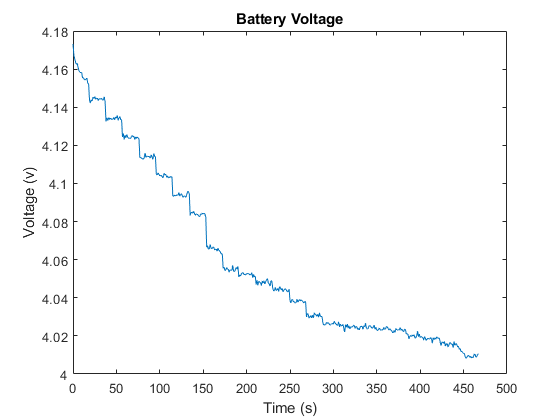

f1 = figure(1); clf;
plot(battery.battery_true.v.Time, battery.battery_true.v.Data);
xlabel("Time (s)");
ylabel("Voltage (v)");
title("Battery Voltage");

% .25 because it will be stored in the db at 4hz
x = 0:.25:time.Time(end)

x =          0    0.2500    0.5000    0.7500    1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000    4.2500    4.5000    4.7500    5.0000    5.2500    5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000   10.2500   10.5000   10.7500   11.0000   11.2500   11.5000   11.7500   12.0000   12.2500


#### Back to the subject of different sample rates, there are also different end-times. in this case, we want to preserve the additional .5 found in time.Time(end) vs the the time found in battery.battery_true.v.Time(end). This is because the battery is sampled at whole seconds, so the simulation carried on for an additional .5 seconds before the battery data was sampled again. See below for the end times and length of time and data vectors.

x(end)

ans = 467.5000

battery.battery_true.v.Time(end)

ans = 467

#### y has an extra entry, which is ok, we will drop it as well. There could be a case where it has two or three extra entries, so handle that with a little if logic

- NOTE - "interp" isn't the best choice to use, continue below and see how it compares to using "resample"

y = interp(battery.battery_true.v.Data, 4)'

y =     4.1732    4.1705    4.1686    4.1675    4.1672    4.1657    4.1649    4.1649    4.1654    4.1642    4.1633    4.1631    4.1635    4.1622    4.1615    4.1617    4.1625    4.1619    4.1617    4.1622    4.1630    4.1618    4.1608    4.1604    4.1605    4.1591    4.1583    4.1583    4.1589    4.1578    4.1574    4.1576    4.1583    4.1574    4.1570    4.1573    4.1582    4.1575    4.1573    4.1576    4.1582    4.1567    4.1556    4.1552    4.1554    4.1544    4.1540    4.1545    4.1555    4.1545


if length(y) > length(x)
    disp('truncating y');
    amt = length(y) - length(x);
    y = y(1:end-amt)
end

truncating y


y =     4.1732    4.1705    4.1686    4.1675    4.1672    4.1657    4.1649    4.1649    4.1654    4.1642    4.1633    4.1631    4.1635    4.1622    4.1615    4.1617    4.1625    4.1619    4.1617    4.1622    4.1630    4.1618    4.1608    4.1604    4.1605    4.1591    4.1583    4.1583    4.1589    4.1578    4.1574    4.1576    4.1583    4.1574    4.1570    4.1573    4.1582    4.1575    4.1573    4.1576    4.1582    4.1567    4.1556    4.1552    4.1554    4.1544    4.1540    4.1545    4.1555    4.1545


#### Now replot the data and verify its integrity

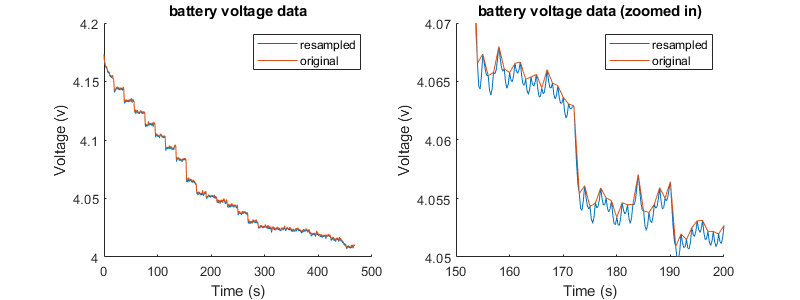

f2 = figure(2); clf;
f2.Position = [0 0 800 300];
subplot(1,2,1);
hold on;
plot(x, y, 'DisplayName', 'resampled');
plot(battery.battery_true.v.Time, battery.battery_true.v.Data, 'DisplayName', 'original');
hold off;
xlabel("Time (s)");
ylabel("Voltage (v)");
title("battery voltage data");
legend;
subplot(1,2,2);
hold on;
plot(x, y, 'DisplayName', 'resampled');
plot(battery.battery_true.v.Time, battery.battery_true.v.Data, 'DisplayName', 'original');
hold off;
xlabel("Time (s)");
ylabel("Voltage (v)");
title("battery voltage data (zoomed in)");
legend;
ylim([4.05, 4.07]);
xlim([150, 200]);

#### Interpolate all battery variables, then create a timetable that will be used to synchronize the rest of the data and be inserted into the database

- NOTE - the below function and above plots use the built in function "interp", but look at the function "sync_telemetry_data" for a better implementation that uses "resample"

% sample_rate = 4; %hz
% sample_interval = 1/sample_rate;
% battery_vars = [];
% var_names = {};
% fn = fieldnames(battery);
% for k=1:numel(fn)
%     params = fieldnames(battery.(fn{k}));
%     for j = 1:length(params)
%         battery_synced.(fn{k}).time = [time.Time(1):sample_interval:time.Time(end)]';
%         battery_synced.(fn{k}).(params{j}) = interp(battery.(fn{k}).(params{j}).Data, sample_rate);
%         if length(battery_synced.(fn{k}).(params{j})) > length(battery_synced.(fn{k}).time)
%             amt = length(battery_synced.(fn{k}).(params{j})) - length(battery_synced.(fn{k}).time);
%             battery_synced.(fn{k}).(params{j}) = battery_synced.(fn{k}).(params{j})(1:end-amt);
%             battery_vars = [battery_vars, battery_synced.(fn{k}).(params{j})];
%             var_names = [var_names, sprintf("%s_%s", fn{k}, params{j})];
%         end
%     end
% end
% battery_tt = array2timetable(battery_vars, 'SampleRate', 4, 'VariableNames', var_names);
% clear('battery_synced', 'amt', 'battery_vars', 'var_names', 'params', 'fn');

### Repeat this process with other telemetry data sources

- notice the above code has been turned into a function now, so we will redo the battery table and take advantage of the more robust function

sample_rate = 4;

#### get the battery data and show the better upsampling

battery_tt = sync_telemetry_data(battery, sample_rate, time.Time(:))

battery_tt = 1871×9 timetable
      Time      battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var
    ________    ______________    ______________    ______________    ______________    _____________    _____________    _____________    _________________    _________________

    0 sec           4.1732                 1            0.0011            26.115              4.2                 1            0.0011                0                  0.003    
    0.25 sec        4.1732                 1            0.001

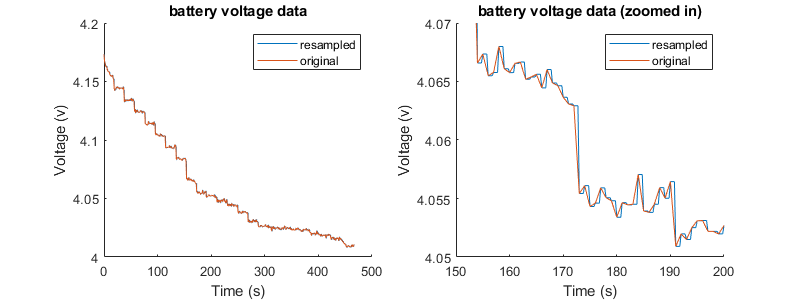

f3 = figure(3); clf;
f3.Position = [0 0 800 300];
subplot(1,2,1);
hold on;
plot(seconds(battery_tt.Time(:)), battery_tt.battery_true_v(:), 'DisplayName', 'resampled');
plot(battery.battery_true.v.Time, battery.battery_true.v.Data, 'DisplayName', 'original');
hold off;
xlabel("Time (s)");
ylabel("Voltage (v)");
title("battery voltage data");
legend;
subplot(1,2,2);
hold on;
plot(seconds(battery_tt.Time), battery_tt.battery_true_v, 'DisplayName', 'resampled');
plot(battery.battery_true.v.Time, battery.battery_true.v.Data, 'DisplayName', 'original');
hold off;
xlabel("Time (s)");
ylabel("Voltage (v)");
title("battery voltage data (zoomed in)");
legend;
ylim([4.05, 4.07]);
xlim([150, 200]);

### The resampled function looks much better than before!

### Control, environment, motor, and position data

Notice the different sample rates. 

errors_tt = sync_telemetry_data(errors, sample_rate, time.Time(:))

errors_tt = 1871×5 timetable
      Time      euclidean_pos_err    pos_err_x_pos_err    pos_err_y_pos_err    ctrl_err_x_error    ctrl_err_y_error
    ________    _________________    _________________    _________________    ________________    ________________

    0 sec               0.52                 -0.2                 0.48              0.14623            -0.66339    
    0.25 sec         0.49257             -0.23462               0.4331              0.34353            -0.43636    
    0.5 sec          0.43125             -0.31288              0.29679             0.022076            -0.37931    
    0.75 sec         0.42951             -0.42424             0.067055              0.56041            -0.11256    
  

environment_tt = sync_telemetry_data(environment, sample_rate, time.Time(:))

environment_tt = 1871×3 timetable
      Time      wind_gust-1    wind_gust-2    wind_gust-3
    ________    ___________    ___________    ___________

    0 sec          3.1623          2.0197        4.0475  
    0.25 sec       2.8484       -0.032396        0.3548  
    0.5 sec        3.3345          2.5065        2.3365  
    0.75 sec       2.3159          1.6796        2.9304  
    1 sec          3.5164          2.4822        3.5988  
    1.25 sec        3.037          1.0902       0.84692  
    1.5 sec         2.276          2.2665         1.682  
    1.75 sec        1.737          2.0328        4.0023  
    2 sec          1.6306        -0.43305         2.958  
    2.25 sec       3.

motors_tt = sync_telemetry_data(motors, sample_rate, time.Time(:))

motors_tt = 1871×26 timetable
      Time      m1_rpm    m1_etorque    m1_current    m2_rpm    m2_etorque    m2_current    m2_r_hat     m2_r_var     m3_rpm    m3_etorque    m3_current    m4_rpm    m4_etorque    m4_current    m5_rpm    m5_etorque    m5_current    m6_rpm    m6_etorque    m6_current    m7_rpm    m7_etorque    m7_current    m8_rpm    m8_etorque    m8_current
    ________    ______    __________    __________    ______    __________<

position_tt = sync_telemetry_data(position, sample_rate, time.Time(:))

position_tt = 1871×6 timetable
      Time      gps-1     gps-2     gps-3     true-1    true-2    true-3
    ________    ______    ______    ______    ______    ______    ______

    0 sec       49.654    25.413    2.7741      49.6     25.23         3
    0.25 sec    49.456    25.186    3.0126    49.565    25.183    2.9573
    0.5 sec     49.778    25.129    3.0531    49.487    25.047    2.9152
    0.75 sec     49.24    24.863    2.8213    49.376    24.817    2.9062
    1 sec       49.155     24.63    2.9433    49.261    24.536    2.9083
    1.25 sec    49.163    24.165    2.9472    49.155     24.26     2.906
    1.5 sec     49.021    2

### **Merge the timetables**

- rename some variables if needed, delete the individual tables since they aren't needed any more

flight_telemetry_tb = [battery_tt environment_tt motors_tt errors_tt position_tt];
clear('battery_tt', 'environment_tt', 'motors_tt', 'errors_tt', 'position_tt');
flight_telemetry_tb.Properties.VariableNames{'pos_err_x_pos_err'} = 'x_pos_err';
flight_telemetry_tb.Properties.VariableNames{'pos_err_y_pos_err'} = 'y_pos_err';
flight_telemetry_tb.Properties.VariableNames{'ctrl_err_x_error'}  = 'x_ctrl_err';
flight_telemetry_tb.Properties.VariableNames{'ctrl_err_y_error'}  = 'y_ctrl_err';
flight_telemetry_tb.Properties.VariableNames{'gps-1'}  = 'x_pos_gps';
flight_telemetry_tb.Properties.VariableNames{'gps-2'}  = 'y_pos_gps';
flight_telemetry_tb.Properties.VariableNames{'gps-3'}  = 'z_pos_gps';
flight_telemetry_tb.Properties.VariableNames{'true-1'}  = 'x_pos_true';
flight_telemetry_tb.Properties.VariableNames{'true-2'}  = 'y_pos_true';
flight_telemetry_tb.Properties.VariableNames{'true-3'}  = 'z_pos_true';
flight_telemetry_tb.Properties.VariableNames{'wind_gust-1'}  = 'wind_gust_x';
flight_telemetry_tb.Properties.VariableNames{'wind_gust-2'}  = 'wind_gust_y';
flight_telemetry_tb.Properties.VariableNames{'wind_gust-3'}  = 'wind_gust_z';
flight_telemetry_tb.Properties.DimensionNames{1} = 'dt';
flight_telemetry_tb

flight_telemetry_tb = 1871×49 timetable
       dt       battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_etorque    m1_current    m2_rpm    m2_etorque    m2_current    m2_r_hat     m2_r_var     m3_rpm    m3_etorque    m3_current    m4_rpm    m4_etorque    m4_current    m5_rpm    m5_etorque    m5_current    

### Convert the time vector duration to a datetime

dt_start.Format = 'MM-dd-uuuu HH:mm:ss.SSS';
dt_stop.Format = 'MM-dd-uuuu HH:mm:ss.SSS';
time_vec = datetime([dt_start: seconds(1/sample_rate) : dt_stop]');
flight_telemetry_tb.dt = time_vec

flight_telemetry_tb = 1871×49 timetable
              dt               battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_etorque    m1_current    m2_rpm    m2_etorque    m2_current    m2_r_hat     m2_r_var     m3_rpm    m3_etorque    m3_current    m4_rpm    m4_etorque    m4_current    m5_rpm    m5_etorque    m5_current

### Make sure there are no required missing values

- this could typically happen with battery data since it is sampled at a lower frequency than other telemetry data

missing_v = sum(ismissing(flight_telemetry_tb.battery_true_v));
missing_z = sum(ismissing(flight_telemetry_tb.battery_true_z));
missing_i = sum(ismissing(flight_telemetry_tb.battery_true_i));
x = 1:1:20;
vals_v = flight_telemetry_tb.battery_true_v(end-20-missing_v+1:end-missing_v);
vals_z = flight_telemetry_tb.battery_true_z(end-20-missing_z+1:end-missing_z);
vals_i = flight_telemetry_tb.battery_true_i(end-20-missing_i+1:end-missing_i);
poly_v = polyfit(x, vals_v, 1);
poly_z = polyfit(x, vals_z, 1);
poly_i = polyfit(x, vals_i, 1);
missing_vals_v = zeros(1, missing_v);
missing_vals_z = zeros(1, missing_z);
missing_vals_i = zeros(1, missing_i);
for i = 1:missing_v
    missing_vals_v(1,i) = polyval(poly_v, 20+i);
    missing_vals_z(1,i) = polyval(poly_z, 20+i);
    missing_vals_i(1,i) = polyval(poly_i, 20+i);
end

idx_v = find(ismissing(flight_telemetry_tb.battery_true_v));
idx_z = find(ismissing(flight_telemetry_tb.battery_true_z))

idx_z =         1870
        1871


idx_i = find(ismissing(flight_telemetry_tb.battery_true_i))


idx_i =

  0×1 empty double column vector




for i = 1:length(idx_z)
    flight_telemetry_tb.battery_true_v(idx_z(i)) = polyval(poly_v, 20+i);
    flight_telemetry_tb.battery_true_z(idx_z(i)) = polyval(poly_z, 20+i);
    flight_telemetry_tb.battery_true_i(idx_z(i)) = polyval(poly_i, 20+i);
end
flight_telemetry_tb = timetable2table(flight_telemetry_tb)

flight_telemetry_tb = 1871×50 table
              dt               battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_etorque    m1_current    m2_rpm    m2_etorque    m2_current    m2_r_hat     m2_r_var     m3_rpm    m3_etorque    m3_current    m4_rpm    m4_etorque    m4_current    m5_rpm    m5_etorque    m5_current 

### Insert the telemetry data into the database

- NOTE - there is an active question on matlab forum regarding miliseconds here [https://www.mathworks.com/matlabcentral/answers/685033-sqlwrite-broken-in-r2020b-vs-r2020a-for-date-time-types](https://www.mathworks.com/matlabcentral/answers/685033-sqlwrite-broken-in-r2020b-vs-r2020a-for-date-time-types) 

% connect to the database
conn = db_connect('nasadb');
% write the data to the database
sqlwrite(conn, 'flight_telemetry_tb', flight_telemetry_tb);

Error using database.odbc.connection/sqlwrite (line 245)
ODBC Error: ODBC Driver Error: ERROR: duplicate key value violates unique constraint "flight_telemetry_tb_dt_key"
DETAIL: Key (dt)=(2021-07-30 10:53:39) already exists.;
Error while executing the query.

conn.commit();
conn.close();
clear conn;

- dump the table to a file as a workaround

- use a code editor to open the file as excel truncates and rounds the date

writetable(flight_telemetry_tb, 'flight_telemetry_tb.csv', 'Delimiter', ',')










